## ESTIMACIÓN DE ESTADO CON FILTROS DE LOCALIZACIÓN (EKF, UKF Y MCL)

Se simula un robot móvil diferencial en un mapa binario de ocupación. La pose se representa mediante posición y orientación. El modelo de movimiento y las mediciones GPS e IMU aportan información con incertidumbre.

Se comparan tres técnicas de localización probabilística:

- Filtro de Kalman extendido (EKF)

- Filtro de Kalman unscented (UKF)

- Localización Monte Carlo (MCL)

La evaluación comprende predicción, corrección, trayectoria, evolución temporal y métricas de error.

clear all; close all; clc
addpath(genpath('auxiliar'));

## DEFINICION DE RUTA

start = [5 35 0]; % [x, y, theta]
goal  = [22 3 0]; % [x, y, theta]

## CARGA DEL MAPA Y DEFINICIÓN DE RUTA

x0 = start(1);
y0 = start(2);

xf = goal(1);
yf = goal(2);

[mapOriginal, mapPlan] = cargar_mapa('complexMap',x0, y0, xf, yf); %complexMap

## PLANIFICACIÓN DE RUTA

waypoints = planificar_ruta(mapPlan, start, goal);

## CONTROLADOR ROBOT

controller = controlador_robot(waypoints);

## INICIALIZACION ALGORITMOS

Los tres estimadores parten de una pose inicial perturbada. EKF y UKF mantienen una media y una covarianza P; MCL mantiene 300 hipótesis ponderadas. Q_gps y Q_imu representan varianzas de medición, y R_odom representa incertidumbre del movimiento.

% Inicialización de los estados reales y estimados, y de las covarianzas

% Estado real inicial (sin error)
x_true = [x0; y0; 0];

% Estado estimado inicial para EKF y UKF (con pequeño error inicial)
x_ekf = x_true + [0.2; -0.2; 0.05];
x_ukf = x_ekf;
x_mcl = x_ekf;

% Covarianza inicial del estimador (incertidumbre sobre x_ekf, x_ukf)
P_ekf = eye(3)*0.01;
P_ukf = P_ekf;

% Ruido de sensores (GPS y IMU)
Q_gps = diag([0.9, 0.9]).^2;  % Ruido en posición (metros^2)
Q_imu = deg2rad(20)^2;        % Ruido en orientación (radianes^2)
Q = blkdiag(Q_gps, Q_imu);    % Matriz de covarianza combinada del sensor

% Ruido del modelo de movimiento (odometría)
R_odom = diag([0.2, 0.2, 0.1]).^2;

% Parámetros del UKF
alpha = 1e-3;
beta = 2;
kappa = 0;
L = 3; % Dimensión del estado
lambda = alpha^2*(L + kappa) - L;
gamma = sqrt(L + lambda); % Escalado de los sigma points
wm = [lambda/(L + lambda), repmat(1/(2*(L + lambda)), 1, 2*L)];
wc = wm; wc(1) = wc(1) + (1 - alpha^2 + beta);

% Parametros MCL
N_particles = 300;
particles = repmat(x_ekf, 1, N_particles) + randn(3, N_particles) .* [0.2; 0.2; 0.1];
weights = ones(1, N_particles) / N_particles;
w_slow = 0;
w_fast = 0;
alpha_slow = 0.01; % Modificable por el alumno
alpha_fast = 0.1; % Modificable por el alumno


## SIMULACIÓN (NO MODIFICAR)

El ciclo integra el movimiento a 10 Hz. EKF y UKF se corrigen con GPS e IMU cuando hay GPS válido (1 Hz); entre llamadas se propaga la pose y se suma R_odom a P. MCL utiliza la IMU en cada iteración. La parada exige que las tres poses estimadas estén dentro de 0,4 m de la meta; no garantiza que la pose real cumpla esa condición.

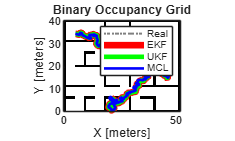

dt = 0.1;
maxSteps = 1000;
tol = 0.4;
gps_interval = round(1 / dt);  % 1 Hz

xHistEKF = zeros(3, maxSteps);
xHistUKF = zeros(3, maxSteps);
xTrueHist = zeros(3, maxSteps);
zIMUHist = zeros(1, maxSteps);
zGPSHist = nan(2, maxSteps);
odoHist = zeros(3, maxSteps);

latEKF = zeros(1, maxSteps); latUKF = zeros(1, maxSteps); latMCL = zeros(1, maxSteps);


figure; ax = axes;
show(mapOriginal, 'Parent', ax); hold(ax, 'on');
trajReal = animatedline('Color',[0.5 0.5 0.5] , 'LineStyle', ':', 'LineWidth', 1.5);
trajEstEKF = animatedline('Color', 'r', 'LineStyle', '-', 'LineWidth', 5);
trajEstUKF = animatedline('Color', 'g', 'LineStyle', '-', 'LineWidth', 3.5);
trajEstMCL = animatedline('Color', 'b', 'LineStyle', '-', 'LineWidth', 2);
legend('Real','EKF','UKF','MCL');

for k = 1:maxSteps

    z_control = simulate_sensors(x_true, Q_gps, Q_imu);
    [v, w] = controller(z_control');
    u = [v; w];
    x_true = motion_model(x_true, u, dt);

    if mod(k, gps_interval) == 0
        z = simulate_sensors(x_true, Q_gps, Q_imu);
    else
        gps_noise = [NaN; NaN];
        imu_noise = randn() * sqrt(Q_imu);
        z = [gps_noise; wrapToPi(x_true(3) + imu_noise)];
    end

    odo = motion_model(x_ekf, u, dt);

    % MCL
    t0 = tic;
    [particles, weights, x_mcl, w_slow, w_fast] = mcl_localization(particles, weights, u, z, R_odom, Q, dt, w_slow, w_fast, alpha_slow, alpha_fast);
    latMCL(k) = toc(t0);

    if all(~isnan(z(1:2)))
        % EKF
        t0 = tic;
        [x_ekf, P_ekf] = ekf_localization(x_ekf, P_ekf, u, z, R_odom, Q, dt);
        latEKF(k) = toc(t0);
        % UKF
        t0 = tic;
        [x_ukf, P_ukf] = ukf_localization(x_ukf, P_ukf, u, z, R_odom, Q, dt, gamma, wm, wc);
        latUKF(k) = toc(t0);
    else
        x_ekf = motion_model(x_ekf, u, dt);
        x_ekf(3) = wrapToPi(x_ekf(3));
        P_ekf = P_ekf + R_odom;

        x_ukf = motion_model(x_ukf, u, dt);
        x_ukf(3) = wrapToPi(x_ukf(3));
        P_ukf = P_ukf + R_odom;
    end

    xHistEKF(:,k) = x_ekf;
    xHistUKF(:,k) = x_ukf;
    xHistMCL(:,k) = x_mcl;
    xTrueHist(:,k) = x_true;
    zGPSHist(:,k) = z(1:2);
    zIMUHist(k) = z(3);
    odoHist(:,k) = odo;

    addpoints(trajReal, x_true(1), x_true(2));
    addpoints(trajEstEKF, x_ekf(1), x_ekf(2));
    addpoints(trajEstUKF, x_ukf(1), x_ukf(2));
    addpoints(trajEstMCL, x_mcl(1), x_mcl(2));

    if mod(k, 5) == 0
        drawnow; 
    end

    dist_ekf = norm(x_ekf(1:2) - goal(1:2)');
    dist_ukf = norm(x_ukf(1:2) - goal(1:2)');
    dist_mcl = norm(x_mcl(1:2) - goal(1:2)');
    
    if all([dist_ekf, dist_ukf, dist_mcl] < tol)
        disp("¡Ruta completada!");
        break;
    end

end

exportgraphics(ax, 'map_trajectory.png', 'Resolution', 800);

## GRÁFICAS COMPARATIVAS

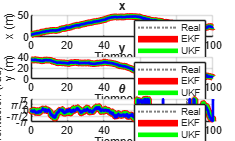

graficar_evolucion_estados(xTrueHist, xHistEKF, xHistUKF, xHistMCL, k, 'comparativa_x_y_theta.png')

## METRICAS


results = calcular_metricas(xTrueHist(:,1:k), ...
    struct('EKF', xHistEKF(:,1:k), 'UKF', xHistUKF(:,1:k), 'MCL', xHistMCL(:,1:k)), ...
    struct('EKF', P_ekf, 'UKF', P_ukf), ...
    Q, ...
    struct('EKF', latEKF(1:k), 'UKF', latUKF(1:k), 'MCL', latMCL(1:k)) ...
);

    Filtro     ATE_media_m    RMSE_pos_m    RMSE_theta_deg    RPE_incremento_m    Drift_neto_m    Error_final_m     STD_m     Latencia_ms_llamadas    Frecuencia_llamadas_Hz    NEES    NIS_1D    NIS_3D
    _______    ___________    __________    ______________    ________________    ____________    _____________    _______    ____________________    ______________________    ____    ______    ______

    {'EKF'}      0.76848       0.84356          13.982             0.2431           0.20441          0.32013       0.34807          0.33985                


guardar_formato_tum('truth.txt',     xTrueHist(:,1:k), dt);

Guardado en formato TUM: truth.txt


guardar_formato_tum('ekf_est.txt',   xHistEKF(:,1:k), dt);

Guardado en formato TUM: ekf_est.txt


guardar_formato_tum('ukf_est.txt',   xHistUKF(:,1:k), dt);

Guardado en formato TUM: ukf_est.txt


guardar_formato_tum('mcl_est.txt',   xHistMCL(:,1:k), dt);

Guardado en formato TUM: mcl_est.txt


## MODELO MOVIMIENTO

function x_new = motion_model(x, u, dt)
    v = u(1); w = u(2); theta = x(3);
    x_new = x + [v*cos(theta); v*sin(theta); w]*dt;
    x_new(3) = wrapToPi(x_new(3));
end

## SENSORES

function z = simulate_sensors(x, Q_gps, Q_imu)
    gps_noise = mvnrnd([0; 0], Q_gps)';
    imu_noise = randn() * sqrt(Q_imu);
    z = [x(1:2) + gps_noise; wrapToPi(x(3) + imu_noise)];
end

## FILTRO DE KALMAN EXTENDIDO (EKF)

Predicción: la función motion_model desplaza la pose con las velocidades lineal y angular. La jacobiana F describe cómo una pequeña variación de orientación afecta a la posición. La incertidumbre se propaga mediante P⁻ = F P Fᵀ + R.

Corrección: corregir_estado selecciona mediciones válidas, calcula la innovación y su covarianza S, y obtiene K = P⁻ Hᵀ S⁻¹. La pose se corrige con K por la innovación y P se actualiza mediante la forma de Joseph. Los ángulos se normalizan para evitar discontinuidades de 2π.

function [x,P] = ekf_localization(x,P,u,z,R,Q,dt)
    theta = x(3); v = u(1);
    F = [1 0 -v*sin(theta)*dt; 0 1 v*cos(theta)*dt; 0 0 1];
    x = motion_model(x,u,dt); P = F*P*F'+R;
    [x,P] = corregir_estado(x,P,z,Q);
end


## FILTRO DE KALMAN UNSCENTED (UKF)

Predicción: para un estado de dimensión tres se construyen siete puntos sigma mediante Cholesky de P. Cada punto pasa por motion_model. Los pesos wm y wc reconstruyen la media y la covarianza; para la orientación se utiliza una media circular. Se añade R a la covarianza predicha.

Corrección: como la observación es directa, corregir_estado aplica la misma corrección de Kalman que en EKF utilizando la covarianza predicha completa. UKF evita calcular una jacobiana, a cambio de propagar varias poses.

function [x, P] = ukf_localization(x, P, u, z, R, Q, dt, gamma, wm, wc)
    % UKF usando los pesos y escalado de la plantilla original.
    Lx = numel(x);
    nsigma = 2*Lx+1;

    % 1. Puntos sigma y prediccion no lineal
    P = (P+P')/2;
    jitter = 1e-12;
    [A,flag] = chol(P+jitter*eye(Lx),'lower');
    while flag ~= 0 && jitter < 1
        jitter = jitter*10;
        [A,flag] = chol(P+jitter*eye(Lx),'lower');
    end
    if flag ~= 0
        error('UKF: la covarianza P no es definida positiva.');
    end
    X = [x, x+gamma*A, x-gamma*A];
    X(3,:) = wrapToPi(X(3,:));
    X_pred = zeros(Lx,nsigma);
    for i=1:nsigma
        X_pred(:,i) = motion_model(X(:,i),u,dt);
    end

    % Media circular para theta
    x_pred = X_pred*wm(:);
    x_pred(3) = atan2(sum(wm.*sin(X_pred(3,:))), ...
                      sum(wm.*cos(X_pred(3,:))));
    P_pred = R;
    for i=1:nsigma
        dx = X_pred(:,i)-x_pred;
        dx(3) = wrapToPi(dx(3));
        P_pred = P_pred+wc(i)*(dx*dx');
    end
    P_pred = (P_pred+P_pred')/2;

    % Observacion lineal parcial: incluye todo el ruido de proceso.
    [x,P] = corregir_estado(x_pred,P_pred,z,Q);
end


## LOCALIZACIÓN MONTE CARLO (MCL)

Predicción: cada una de las 300 partículas representa una pose posible. Se propaga con motion_model y ruido gaussiano de covarianza R.

Ponderación: las partículas compatibles con las mediciones disponibles reciben mayor peso. Se calculan log-verosimilitudes y se normalizan de forma estable. La posición estimada es la media ponderada y la orientación se obtiene con una media circular.

Remuestreo: cuando el número efectivo de partículas cae por debajo de N/2 o llega GPS, se aplica remuestreo sistemático. Las medias lenta y rápida de verosimilitud permiten inyectar nuevas hipótesis cerca de la medición completa. No se utiliza una distribución global de partículas sobre el mapa.

function [particles, weights, x_est, w_slow, w_fast] = mcl_localization(particles, weights, u, z, R, Q, dt, w_slow, w_fast, alpha_slow, alpha_fast)
    % MCL adaptativo: prediccion, likelihood, inyeccion y remuestreo.
    % particles: 3xN; weights: 1xN; z(1:2) NaN sin GPS.
    N = size(particles,2);
    weights = weights(:)';
    weights = weights/max(sum(weights),realmin);

    % 1. Propagacion con ruido aditivo de proceso R
    Lr = chol(R+1e-12*eye(3),'lower');
    for i=1:N
        particles(:,i) = motion_model(particles(:,i),u,dt) ...
                          + Lr*randn(3,1);
    end
    particles(3,:) = wrapToPi(particles(3,:));

    % 2. Pesos con dimensiones disponibles (IMU siempre, GPS a 1 Hz)
    valid = ~isnan(z);
    idx = find(valid);
    if isempty(idx)
        x_est = [particles(1:2,:)*weights(:); atan2(sum(weights.*sin(particles(3,:))),sum(weights.*cos(particles(3,:))))];
        return;
    end
    e = z(idx)-particles(idx,:);
    angleIdx = find(idx==3,1);
    if ~isempty(angleIdx)
        e(angleIdx,:) = wrapToPi(e(angleIdx,:));
    end
    Qsub = Q(idx,idx);
    % log-verosimilitud gaussiana, sin constante comun
    Lq = chol(Qsub+1e-12*eye(numel(idx)),'lower');
    whitened = Lq\e;
    loglik = -0.5*sum(whitened.^2,1);
    logpost = log(max(weights,realmin))+loglik;
    unnorm = exp(logpost-max(logpost));
    mass = sum(unnorm);
    w_avg = mean(exp(loglik));
    if mass <= realmin
        weights = ones(1,N)/N;
    else
        weights = unnorm/mass;
    end

    % Medias de verosimilitud: utilizan un factor comun estable
    if all(valid(1:2)) && w_slow == 0
        w_slow = w_avg;
        w_fast = w_avg;
    elseif all(valid(1:2))
        w_slow = w_slow + alpha_slow*(w_avg-w_slow);
        w_fast = w_fast + alpha_fast*(w_avg-w_fast);
    end

    % Estimacion antes del remuestreo para no perder informacion
    x_est = [sum(weights.*particles(1,:)); ...
             sum(weights.*particles(2,:)); ...
             atan2(sum(weights.*sin(particles(3,:))), ...
                   sum(weights.*cos(particles(3,:))))];

    % 3. Remuestreo sistematico e inyeccion adaptativa al llegar GPS.
    % Sin GPS la inyeccion global no esta fundamentada espacialmente.
    neff = 1/sum(weights.^2);
    if neff < N/2 || all(valid(1:2))
        cdf = cumsum(weights); cdf(end) = 1;
        positions = ((0:N-1)+rand)/N;
        indices = zeros(1,N);
        j = 1;
        for i=1:N
            while positions(i) > cdf(j)
                j = j+1;
            end
            indices(i) = j;
        end
        newParticles = particles(:,indices);
        if all(valid(1:2)) && w_slow > realmin
            pRandom = max(0,min(1,1-w_fast/w_slow));
            nRandom = sum(rand(1,N) < pRandom);
            if nRandom > 0
                Lqfull = chol(Q+1e-12*eye(3),'lower');
                newParticles(:,1:nRandom) = z + Lqfull*randn(3,nRandom);
                newParticles(3,1:nRandom) = wrapToPi(newParticles(3,1:nRandom));
            end
        end
        particles = newParticles;
        weights = ones(1,N)/N;
    end
end
